# CSR Tracking Example Through Dogleg

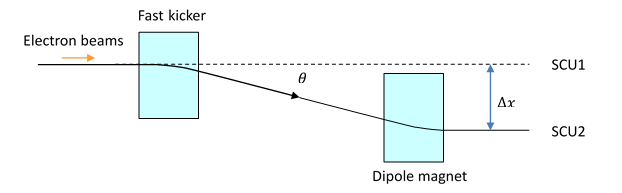

*Requires Lucretia toolbox: download from *[*https://github.com/slaclab/Lucretia*](https://github.com/slaclab/Lucretia)* and add all src/ directories to Matlab search path.*

*Lucretia documentation here: https://www.slac.stanford.edu/accel/ilc/codes/Lucretia/*

## Generate Lucretia lattice for dogleg

ans =      0     1     0     1


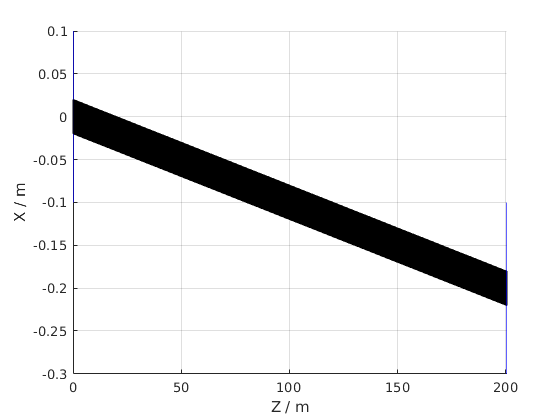

global BEAMLINE
Lb = 0.3 ; % Bend Length [m]
E = 0.1 ; % Design energy [GeV]
Ld = 200 ; % Distance between bends [m]
Theta = 1e-3 ; % Bend angle [rad]
Hgap = 0.02 ; % Half-gap of bend
Fint=0.5;
clight=299792458; Brho = clight/(E*1e9);
BField = Theta/Brho;
BEAMLINE{1,1} = SBendStruc( Lb, BField, Theta, 0, [0 0], Hgap, Fint, 0, 'B1' ) ; BEAMLINE{1}.P=E;
BEAMLINE{2,1} = DrifStruc(Ld,'D1') ; BEAMLINE{2}.P=E;
BEAMLINE{3,1} = SBendStruc( Lb, -BField, -Theta, 0, [0 0], Hgap, Fint, 0, 'B1' ) ; BEAMLINE{3}.P=E;
SetSPositions(1,length(BEAMLINE),0); % Generate S positions of elements
SetFloorCoordinates(1,length(BEAMLINE),zeros(1,6)); %^ Generate survey co-ordinates of elements
FP=FloorPlot; FP.plot2d(1); % Show survey plot of magnets

## Setup Electron Bunch and Twiss Parameters

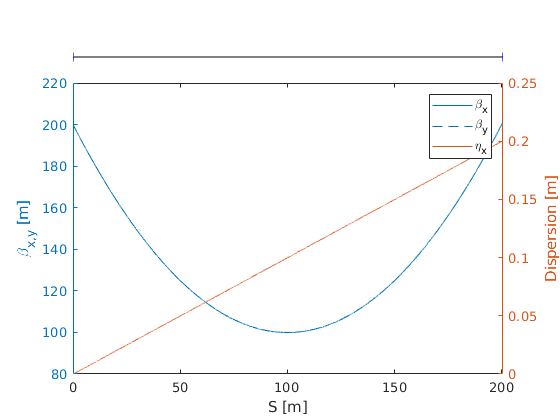

I = InitCondStruc ;
I.Momentum = E ;
I.sigz = 20e-6 ; % 20 um rms bunch length
I.Q = 100e-12 ; % 100pC Bunch charge
I.SigPUncorrel = E*1e-4 ; % Initial uncorrelated energy spread
I.x.NEmit = 0.1e-6 ; I.y.NEmit = 0.1e-6 ; % 0.1 um-rad initial emittance
I.x.Twiss.beta = 200; I.x.Twiss.alpha=1; % Initial horizontal Twiss parameters
I.y.Twiss.beta = 200; I.y.Twiss.alpha=1; % Initial vertical Twiss parameters
Twiss=TwissPlot(1,length(BEAMLINE),I,[1 1 0],0.01) ; % Plot Twiss parameters

## Generate Macro Particle Representation of Electron Bunch and Perform Tracking - First with No CSR as check

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000409 



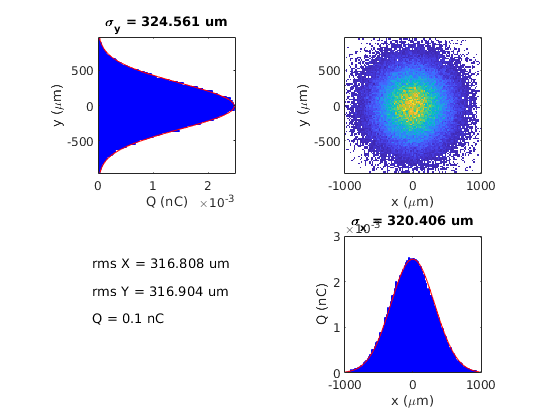

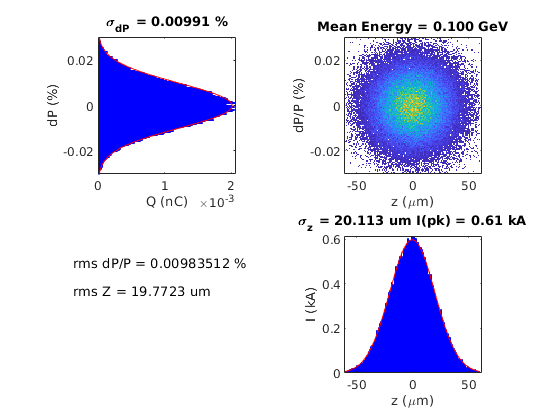

Beam = MakeBeam6DGauss(I,1e5,3,1); % Generate 100k macro particles
[~,BeamOut] = TrackThru(1,length(BEAMLINE),Beam,1,1); % Test track through lattice without CSR physics modeling
beamImage(BeamOut); % look at tracked particle distributions

nx = GetNEmitFromBeam(BeamOut,1); % Get horizontal emittance
de_f = std(BeamOut.Bunch.x(6,:))/mean(BeamOut.Bunch.x(6,:)) ; % Final relative energy spread of beam
fprintf('NO CSR Horizontal Emittance = %.2f um-rad\n',nx*1e6);

NO CSR Horizontal Emittance = 0.10 um-rad


## Check some CSR related quantities

- "Overtaking Length" : $L_0 \approx (24\sigma_z\rho^2)^{1/3}$ (transition effects & CSR in drift important if a significant fraction of bend length)

- "Derbenev Criterion" : $\sigma_x\left(\frac{1}{\rho\sigma_z^2}\right)^{1/3}$ (1D simulation OK if << 1)

- Approximate emittance growth in final bend (only includes "steady-state" wake, not very valid if Overtaking length large compared with bend length):

- $\left(\frac{\epsilon}{\epsilon_0}\right)\approx\sqrt{1+\frac{(0.22)^2}{16}\frac{r_e^2N_B^2}{\gamma\epsilon_N\beta}\psi\left(\frac{|\theta^5|L_B}{\sigma_{z_f}^4}\right)^{(2/3)}}$ (see Acc. Handbook Second Edition p.336)

rho=Lb/Theta; % Bending radius [m]
gamma=E/0.511e-3; % Relativistic gamma
sigx = sqrt(I.x.Twiss.beta*(I.x.NEmit/gamma)+[0 (Twiss.etax(end)*de_f)^2]); % Design rms horizontal bunch size in bend 1 and 2
L0 = (24*I.sigz*rho^2)^(1/3) ; % Overtaking length
Derb = sigx*(1/(rho)) ; % Derbenev Criterion
re=2.8179e-15; % classical electron radius
qe=1.6022e-19; % elementary charge
Nb=I.Q/qe; % # electrons
psi=Lb^2*(1+Twiss.alphax(end)^2)+4*Twiss.betax(end)^2+4*Twiss.alphax(end)*Twiss.betax(end)*Lb;
deps = sqrt(1+0.22^2/16*(re^2*Nb^2)/(gamma*I.x.NEmit)*psi*(abs(Theta)^5*Lb/I.sigz^4)^(2/3)) ; % Analytical emit/emit0 for last bend
fprintf('Overtaking Length = %.2f m\n',L0);

Overtaking Length = 3.51 m


fprintf('Derbenev Criterion: Bend 1 = %g Bend 2 = %g \n',Derb);

Derbenev Criterion: Bend 1 = 1.06562e-06 Bend 2 = 1.06765e-06 


fprintf('Analytic estimate of emit/emit0 = %g',deps);

Analytic estimate of emit/emit0 = 1.00586

## Set CSR Tracking Flags and Perform Tracking with 1D CSR Simulation

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000409 



for iele=findcells(BEAMLINE,'Class','SBEN')
  BEAMLINE{iele}.TrackFlag.CSR=-1 ; % 1-d CSR model, automatic charge binning
  BEAMLINE{iele}.TrackFlag.CSR_DriftSplit=50 ; % Model CSR wakes in drift using 50 slices
  BEAMLINE{iele}.Split=50 ; % Use 50 slices for tracking in bends
end
[~,BeamOut] = TrackThru(1,length(BEAMLINE),Beam,1,1); % Perform tracking
beamImage(BeamOut); % look at tracked particle distributions

nx = GetNEmitFromBeam(BeamOut,1); % Get horizontal emittance
de_f = std(BeamOut.Bunch.x(6,:))/mean(BeamOut.Bunch.x(6,:)) ; % Final relative energy spread of beam
fprintf('Horizontal Emittance (with CSR) = %.2f um-rad\n',nx*1e6);

Horizontal Emittance (with CSR) = 0.10 um-rad
